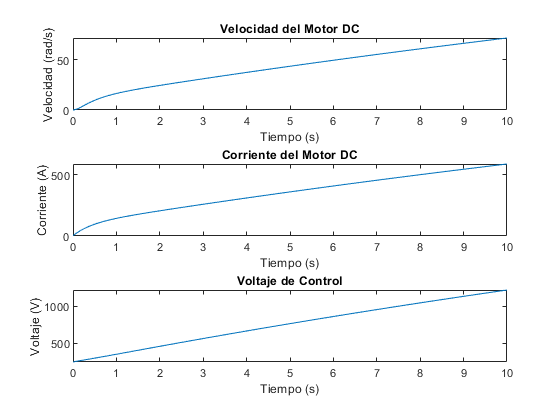

% Parámetros del motor DC
R = 1; % Resistencia (Ohms)
L = 0.5; % Inductancia (H)
K_t = 0.01; % Constante de torque (Nm/A)
K_e = 0.01; % Constante de fuerza contraelectromotriz (V/rad/s)
J = 0.01; % Inercia del rotor (kg.m^2)
B = 0.1; % Coeficiente de fricción (Nm.s)

% Parámetros del controlador PI
Kp = 1; % Ganancia proporcional
Ki = 0.5; % Ganancia integral

% Condiciones iniciales
speed_desired = 100; % Velocidad deseada en rad/s
speed_actual = 0; % Velocidad inicial en rad/s
current = 0; % Corriente inicial en A
voltage = 0; % Voltaje inicial en V
error_integral = 0; % Integral del error

% Tiempo de simulación
dt = 0.01; % Paso de tiempo (s)
t_final = 10; % Tiempo final (s)
time = 0:dt:t_final;

% Variables para guardar resultados
speed_history = zeros(size(time));
current_history = zeros(size(time));
voltage_history = zeros(size(time));

% Simulación
for i = 1:length(time)
    % Error entre velocidad deseada y actual
    error = speed_desired - speed_actual;
    
    % Controlador PI
    error_integral = error_integral + error * dt;
    voltage = Kp * error + Ki * error_integral;
    
    % Actualización de la dinámica del motor
    current_dot = (voltage - R * current - K_e * speed_actual) / L;
    speed_dot = (K_t * current - B * speed_actual) / J;
    
    current = current + current_dot * dt;
    speed_actual = speed_actual + speed_dot * dt;
    
    % Guardar resultados
    speed_history(i) = speed_actual;
    current_history(i) = current;
    voltage_history(i) = voltage;
end

% Graficar resultados
figure;
subplot(3, 1, 1);
plot(time, speed_history);
xlabel('Tiempo (s)');
ylabel('Velocidad (rad/s)');
title('Velocidad del Motor DC');

subplot(3, 1, 2);
plot(time, current_history);
xlabel('Tiempo (s)');
ylabel('Corriente (A)');
title('Corriente del Motor DC');

subplot(3, 1, 3);
plot(time, voltage_history);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Voltaje de Control');